clear all
clc
close all

## Van der Pol tutorial

run Install.m

Please add either tensortoolbox or tensor lab to your path
 You can download the tensortoolbox for matlab from  https://www.tensortoolbox.org
MPT toolbox is not automatically installed


Yalmip and Mosek are not automatically installed



tStart = tic;
disp(' Van der Pol Oscillator tutorial ')

 Van der Pol Oscillator tutorial 



% Set value for epsilon
epsilon = 0.1;

% Load model into sysNonLin
Vanderpol_dist

% Specify matrix before input
% Model structure x(t+1) = f(x)+Bu(t)+Bw w(t)
B = [0;1];

% Bounds on state space 
x1l = -3;   % Lowerbound x1
x1u = 3;   % Upperbound x1
x2l = -3;   % Lowerbound x2
x2u = 3;   % Upperbound x2
sysNonLin.X = Polyhedron(combvec([x1l,x1u],[x2l,x2u])');

MOSEK Version 9.2.5 (Build date: 2020-4-22 22:58:28)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86



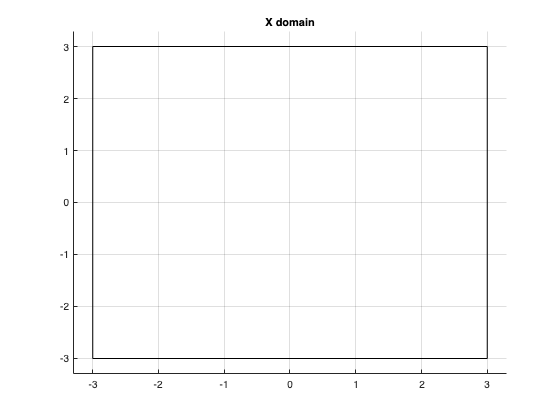

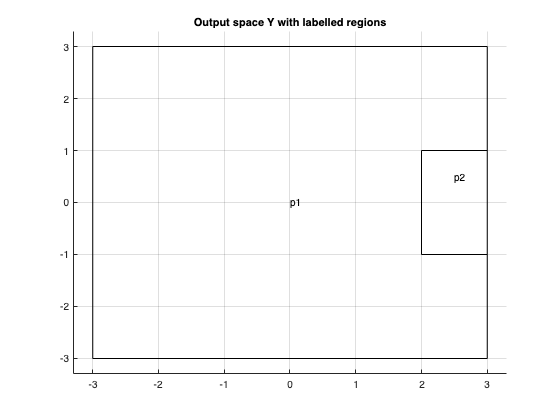


% Bounds on input space
ul = [-1];   % Lowerbound input u
uu = [1];     % Upperbound input u
sysNonLin.U = Polyhedron([ul(1),uu(1)]');

% Specify division of input space for actuation and feedback
% u = uhat+K(x-xhat), uhat \in [ula, uua],
% K(x-xhat) \in [ulf, uuf]
ula = 0.6*ul;   % part of input for actuation (lowerbound)
uua = 0.6*uu;
ulf = ul-ula;   % part of input for feedback (lowerbound)
uuf = uu-uua;

% Stay in bounded region
P1 = Polyhedron(combvec([-3,3],[-3,3])');

% Reach in bounded region
P2 = Polyhedron(combvec([2,3],[-1,1])');

sysNonLin.regions = [P1;P2]; % regions that get specific atomic propositions
sysNonLin.AP = {'p1', 'p2'}; % with the corresponding atomic propositions

Plot_sysLTI(sysNonLin)


% Compute symbolic expression for Taylor expansion and remainder 
% This function assumes a polynomial function!
[T,R,NL] = ComputeTaylorAndRemainder(sysNonLin);

Pre-computation of piecewise-affine approximation for state update of x2 


## 1. Synthesize scLTL formula (or input DFA yourself)

Define (sc)LTL formula 

formula = '(p1 U p2)';  % p1 = safe region, p2 = target region
 
% Translate formula to deterministic finite automaton 
[DFA] = TranslateSpec(formula,sysNonLin.AP);

never { /* (p1 U p2) */
T0_init:
	if
	:: (p1) -> goto T0_init
	:: (p2) -> goto accept_all
	fi;
accept_all:
	skip
}

add state


## 2. Construct abstract model

### Abstraction part 1: PWA approximation

% Define SQUARE partitions and dynamics of PWA approximation
N = [41 41]; % number of grid points in each direction
[sysPWA] = PWAapproximation(sysNonLin,B,T,N,NL);

Performing piecewise-affine approximation for state update of state 2

sysPWA.X = sysNonLin.X;
sysPWA.U = sysNonLin.U;
sysPWA.regions = sysNonLin.regions;
sysPWA.AP = sysNonLin.AP;
[sysPWA.Partition.Uu] = deal(max(abs(ulf),abs(uuf)));

%Quantify difference between original model and PWA approximation
for k = 1:sysPWA.Np
    sysPWA.Partition(k).K = ComputeTaylorAccuracy(sysPWA.Partition(k),R);
end

### Abstraction part 2: gridding

disp('start gridding');tic

start gridding



% Construct abstract inputs
lu = 5; % number of abstract inputs
uhat = linspace(ula(1),uua(1),lu);
[~,idx]=sort(abs(uhat));
uhat=uhat(idx);
l = [600, 600];  % number of grid cells in x1- and x2-direction
tol = 10^-8;

% Grid system with efficient nonlinear gridding
sysAbs = Gridding(sysPWA,uhat,l,tol,'TensorComputation','tensortoolbox');

% Save some extra system parameters into struct
sysAbs.orig = sysNonLin;

% Label the abstract state space
label = zeros(1,prod(l));
[label(1:prod(l))] = deal(1);
index_labels = sysNonLin.regions.contains(sysAbs.states);
[label(index_labels(1,:))] = deal(3);
[label(index_labels(2,:))] = deal(4);
sysAbs.labels = label;

toc

Elapsed time is 2037.786909 seconds.


disp('---> finished gridding')

---> finished gridding



disp('determine partition for each abstract state');tic

determine partition for each abstract state


% Determine for each abstract state in which partition it lies
% Assumes rectangular grid cells
temp = ceil((sysAbs.states-[x1l;x2l])./[x1u-x1l;x2u-x2l].*(N'-1));
sysAbs.Partition = (temp(2,:)-1)*(N(2)-1)+temp(1,:);

## 3. Compute delta based on epsilon

disp('start computing eps delta');tic;

start computing eps delta



% Rewrite (struct --> matrices) to be able to use parallel computing
for i = 1:sysPWA.Np
    Kset(i) = sysPWA.Partition(i).K;
    
    Bset = plus(sysPWA.Partition(i).K,sysAbs.beta);
    Bset = minVRep(Bset);
    sysPWA.Partition(i).Bset = Bset;
    Bset_all(i) = sysPWA.Partition(i).Bset;
    
    Dynamics(i) = sysPWA.Partition(i).Dynamics;
    Uu(:,i) = sysPWA.Partition(i).Uu;
end

% % Compute epsilon bounds for biggest Bset! (hence for partition with
% % largest K)
% Kmax = 0;
% for i = 1:sysPWA.Np
%     K = max(max(Kset(i).V));
%     if K>Kmax
%         Kmax = K;
%         index = i;
%     end
% end

mu = sysPWA.mu;
sigma = sysPWA.sigma;
Beta = sysAbs.beta;

% States that are taken into account when computing D matrix
States = [-0.3696, 2.086, 0.4726, -2.165, 0; 1.774, 0.8801, -1.665, -0.4429,0];
AbstractStateIndex = [];
for i = 1:size(States,2)
    S = States(:,i);
    diff = S-sysAbs.states;
    dis = sqrt(sum(diff.^2,1));
    [~,j] = min(dis);
    Shat = sysAbs.states(:,j);
    AbstractStateIndex = [AbstractStateIndex, j];
end
index = sysAbs.Partition(AbstractStateIndex);
% Compute a suitable weighting matrix for simulation relation 
% ||x-xhat||_D \leq \epsilon
[D, ~] = ComputeD(epsilon,sysPWA,mu,sigma,Bset_all,index,2,Uu(:,1));

% Compute delta for each partition
f_delta = ones(1,sysPWA.Np);
KfK = [];
parfor i = 1:sysPWA.Np
    Bset = plus(Kset(i),Beta);
    Bset = minVRep(Bset);
    
    [delta, Kf] = ComputeDelta2(epsilon,Dynamics(i),mu,sigma,Bset,D,'interface',1,Uu(:,i));

    f_delta(1,i) = delta;
    KfK = [KfK; Kf];
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

MOSEK Version 9.2.5 (Build date: 2020-4-22 22:58:28)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86


MOSEK Version 9.2.5 (Build date: 2020-4-22 22:58:28)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86



for i = 1:sysPWA.Np
    sysPWA.Partition(i).delta = f_delta(1,i);
    sysPWA.Partition(i).Kf = KfK(i,:);
    sysPWA.Partition(i).rel = SimRel(epsilon,sysPWA.Partition(i).delta,eye(2));
end

disp([', epsilon = ', num2str(epsilon), 'delta = ', num2str(f_delta)])

, epsilon = 0.1delta = 0.012146    0.012047    0.011955    0.011848     0.01174    0.011644    0.011555    0.011458    0.011361    0.011262    0.011177    0.011099    0.010998    0.010903    0.010823    0.010742     0.01066     0.01057    0.010487     0.01041     0.01041    0.010487     0.01057     0.01066    0.010742    0.010823    0.010903    0.010998    0.011099    0.011177    0.011262    0.011361    0.011458    0.011555    0.011644     0.01174    0.011848    0.011955    0.012047    0.012146    0.012093    0.012001    0.011901    0.011794    0.011692    0.011596    0.011514     0.01141    0.011312     0.01122    0.011134    0.011048    0.010954    0.010867    0.010778    0.010704    0.010615    0.010525    0.010449    0.010372    0.010372    0.010449    0.010525    0.010615    0.010704    0.010778    0.010867    0.010954    0.011048    0.011134     0.01122    0.011312     0.01141    0.011514    0.011596    0.011692    0.011794    0.011901    0.012001    0.012093    0.012047    0.011


% Define simulation relation
rel = SimRel(epsilon,f_delta,eye(2));

% Determine labelling 
rel.NonDetLabels  = NonDeterministicLabelling(sysAbs.outputs, sysNonLin.regions, rel);
toc    

Elapsed time is 1916.432550 seconds.


disp('---> finished computing eps delta')

---> finished computing eps delta


## Synthesize controller

disp('start computing robust controller')

start computing robust controller



N = 100;     % time horizon

% Get delta in correct shape for SynthesizeRobustController
rel.delta = rel.delta(sysAbs.Partition)';

% Synthesize robust controller
[satProp,pol] = SynthesizeRobustController(sysAbs,DFA, rel, N, false);

 <---- Start computing robust policy 
Elapsed time is 0.034579 seconds.
Convergence reached!
Number of iteration required, k=84
Elapsed time is 1.905381 seconds.
 ----> Finished computing robust policy in 1.9453



disp('---> finished computing robust controller')

---> finished computing robust controller


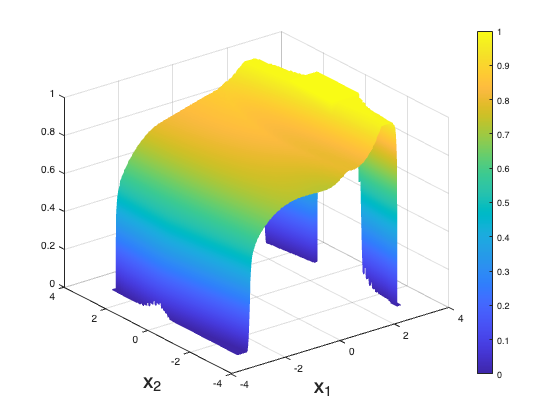


tEnd = toc(tStart);

% Compute Satisfaction probability at initial DFA state
satPropPlot = satProp((0:length(satProp)-1)*length(DFA.S)+DFA.trans(DFA.S0,sysAbs.labels));
[X1hat, X2hat] = ndgrid(sysAbs.hx{1},sysAbs.hx{2});

figure;
surf(X1hat, X2hat,reshape(satPropPlot,l(1),l(2)),'EdgeColor','interp')
xlabel('x_1', 'FontSize', 20)
ylabel('x_2', 'FontSize', 20)
xlim([-4,4]);
ylim([-4,4]);
colorbar

## Display execution time

disp(['Total runtime = ', mat2str(tEnd)])

Total runtime = 3983.331683128


## Simulation

x0 = [-1;1.5];

xsim = [x0];

% first step in DFA
q = DFA.S0;
if P2.contains(x0)
    label = 2;
elseif P1.contains(x0)
    label = 3;
else
    label = 1;
end
q_next = DFA.trans(q,label);

% initial abstract state
diff = x0-sysAbs.states;
dis = sqrt(sum(diff.^2,1));
[~,j] = min(dis);
xhat0 = sysAbs.states(:,j);
xhatsim = [xhat0];

% satisfaction probability of initial state
SatProp = satProp(q,j);
disp(['Value function at x0 equals ', mat2str(SatProp,4),])

Value function at x0 equals 0.8019



% initial input
uhat = pol(:,j, q_next);

% run simulation 
usim = [];
uhatsim = [];
indexing = 1:length(sysAbs.states);
q=q_next;
for i = 1:N
    disp(['x = ', mat2str(xsim(:,i),4), ',    q^+ = ',num2str(q_next)])    % show next continuous state

    if q == DFA.F
        disp("satisfied specification")
        break;
    elseif q == DFA.sink
        disp("failed specification")
        break;
    end
    w = mvnrnd(sysNonLin.mu,sysNonLin.sigma)';

    Pr = sysAbs.Partition(j);     % Partition nr of abstract state
    
    Kf = sysPWA.Partition(Pr).Kf;
    u = uhat+Kf*(xsim(:,end)-xhatsim(:,end));
    usim = [usim, u];
    
    A = sysPWA.Partition(Pr).Dynamics.A;
    B = sysPWA.Partition(Pr).Dynamics.B;
    a = sysPWA.Partition(Pr).Dynamics.a;
    Bw = sysPWA.Partition(Pr).Dynamics.Bw;
    xnext = A*xsim(:,end)+B*u+Bw*w;

    xsim = [xsim,xnext];

    if P2.contains(xsim(:,end))
        label = 2;
    elseif P1.contains(xsim(:,end))
        label = 3;
    else
        label = 1;
    end
    q_next = DFA.trans(q,label);

    % find next abstract state, by looking at the maximizer in R wrt the value function. 
    diff2 = xsim(:,end)-sysAbs.states;
    inR = (([1 1]*((D^.5*diff2).^2)).^.5)<=epsilon;
    indices_valid = indexing(inR);
    satProp_q = satProp(q_next,:);
    [value_max, index_aux] = max(satProp_q(inR));
    j = indices_valid(index_aux); % find maximizing index of abstract state
    xhatnext = sysAbs.states(:,j);
    xhatsim = [xhatsim, xhatnext];

    uhat = [pol(:,j,q_next)];
    uhatsim = [uhatsim, uhat];
    
    q = q_next;
    
    if size(j,2)==0
        q = DFA.sink;
    end
    
end

x = [-1;1.5],    q^+ = 2
x = [-0.9702;1.978],    q^+ = 2
x = [-0.934;2.346],    q^+ = 2
x = [-0.538;2.567],    q^+ = 2
x = [-0.5359;2.688],    q^+ = 2
x = [-0.192;2.489],    q^+ = 2
x = [0.2973;2.707],    q^+ = 2
x = [0.4286;2.714],    q^+ = 2
x = [0.8839;2.711],    q^+ = 2
x = [1.13;2.638],    q^+ = 2
x = [1.454;2.196],    q^+ = 2
x = [1.714;2.185],    q^+ = 2
x = [1.918;0.754],    q^+ = 2
x = [2.155;0.339],    q^+ = 1


satisfied specification


## Show results

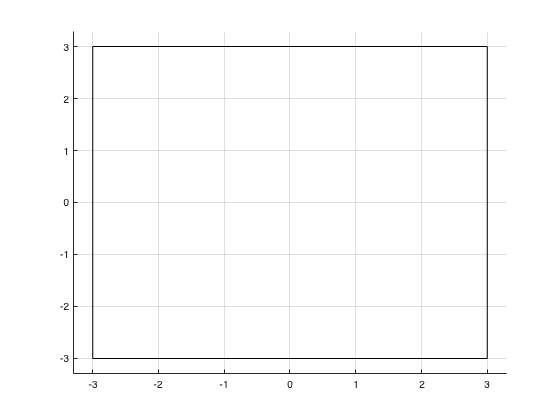

figure;
plot_x = plot(sysNonLin.X);
set(plot_x, 'FaceColor','None');

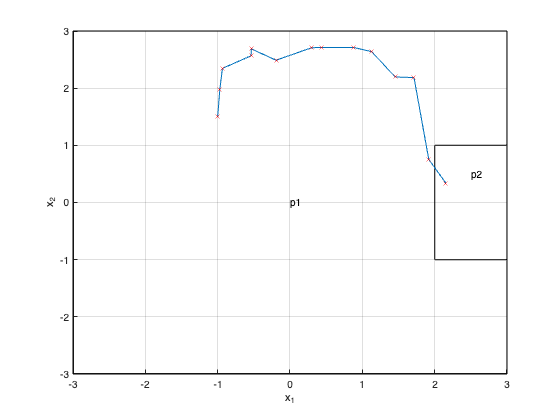

plot_y = plot(sysNonLin.C*sysNonLin.X);
set(plot_y, 'FaceColor','None');
hold on 
for i =1:length(sysNonLin.regions)
    plot_x = plot(sysNonLin.regions(i));
    set(plot_x, 'FaceColor','None');
    hold on
    xc = sysNonLin.regions(i).chebyCenter;
    text(xc.x(1),xc.x(2), sysNonLin.AP{i})
end
xlim([x1l x1u])
ylim([x2l x2u])
xlabel('x_1')
ylabel('x_2')
plot(xsim(1,:),xsim(2,:))
plot(xsim(1,:),xsim(2,:),'rx')